% Copyright (C) <2024>, M Becker
%
% List of the contributors to the development of FLORIDyn: see LICENSE file.
% Description and complete License: see LICENSE file.
	
% This program (FLORIDyn) is free software: you can redistribute it and/or modify
% it under the terms of the GNU Affero General Public License as published by
% the Free Software Foundation, either version 3 of the License, or
% (at your option) any later version.

% This program is distributed in the hope that it will be useful,
% but WITHOUT ANY WARRANTY; without even the implied warranty of
% MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the
% GNU Affero General Public License for more details.

% You should have received a copy of the GNU Affero General Public License
% along with this program (see COPYING file).  If not, see <https://www.gnu.org/licenses/>.
% ======================================================================= %
% Updated: 16. Dez. 2024, M. Becker
% ======================================================================= %

Demonstration of the limited preview mode

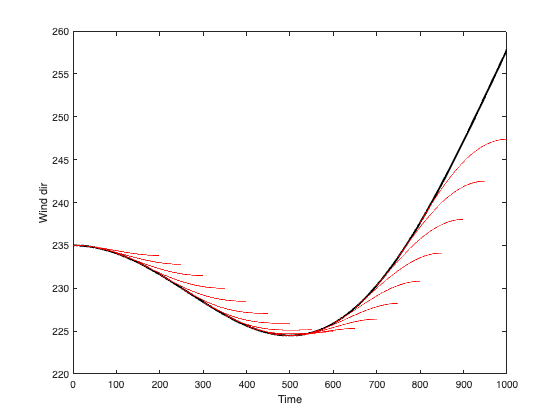

t = linspace(0,1000,1000);
phi     = 0.00003*t.^2 + 10*cos(t/200) + 225;
ph      = 200;
up      = 0:50:800;
trust   = linspace(1,0,ph);
figure
plot(t,phi,'k','LineWidth',2)
hold on
for iU = 1:length(up)
    tu = up(iU):up(iU)+ph;
    phi_relevant = interp1(t,phi,tu);
    p_diff = diff(phi_relevant) .* trust;
    phi_u = cumsum([phi_relevant(1); p_diff(:)]);
    plot(tu,phi_u,'-r')
end
xlim([0, 1000])
ylabel('Wind dir')
xlabel('Time')